scans_filepath = load_rd("KBYX", datetime("19-Apr-2019 01:00"));
rd = read_rd(scans_filepath, 'maxAlt', 2000);
dens = rd{1}.dens.sweeps(1).data;
A = repmat(rd{1}.dens.sweeps(1).az,1,numel(rd{1}.dens.sweeps(1).range))';
id=~isnan(dens);

## Option 1

coef = [abs(sind(A(id))) ones(sum(id,'all'),1)] \ dens(id);
dens2 = dens +  abs(sind(A))*coef(1);

## Option 2

ft = fittype('a + b*abs(sind(x - c))','indep','x');
mdl = fit(A(id),dens(id),ft,'startpoint',[30, 5, 0]);

mdl =      General model:
     mdl(x) = a + b*abs(sind(x - c))
     Coefficients (with 95% confidence bounds):
       a =       14.14  (13.05, 15.23)
       b =       -8.69  (-10.3, -7.084)
       c =        42.2  (37.51, 46.9)

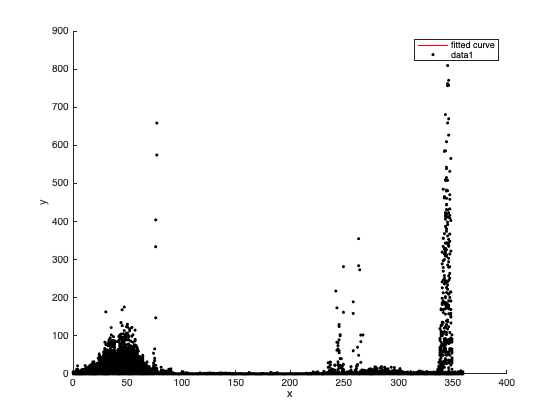

figure; hold on;
plot(mdl)
plot(A(id),dens(id),'.k')

dens2 = dens +  abs(sind(A - mdl.c))* mdl.b;

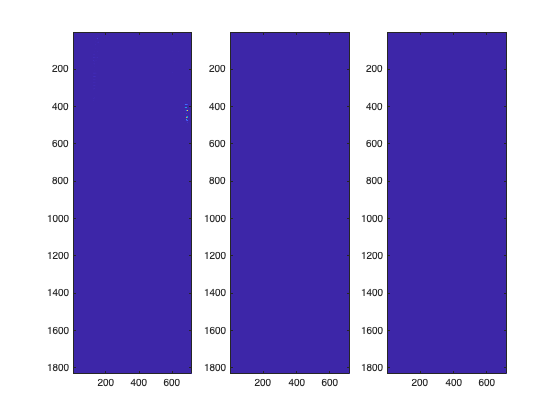

figure; 
subplot(1,3,1);imagesc(dens)
subplot(1,3,2);imagesc(dens2)
subplot(1,3,3);imagesc(dens-dens2)

## Option 3

mdl = fit(A(id),dens(id),'a*(1+c*abs(cosd(x - b)))','startpoint',[50, 120, 1])

figure; hold on;
plot(A(id),dens(id),'.k')
plot(mdl)

dens2 = dens -  mdl.a*(1+mdl.c*abs(cosd(A - mdl.b))) + mdl.a*2;

figure; 
subplot(1,3,1);imagesc(dens); colorbar;
subplot(1,3,2);imagesc(dens2); colorbar;
subplot(1,3,3);imagesc(dens2-dens); colorbar;

## Only angle

mdl2 = fit(A(id),dens(id),'abs(cosd(x - b))','startpoint',120)